# Alpha-Block Pre-Processing

This script provides sections to pre-process and clean the data collected from the **Alpha Block**. The following provides a breakdown of the section. All codes can be run independently of each other.

Sections related to scalp-EEG:

- Section 1: allows the obtention of configurations T7-Oz and T8-Oz

- Section 2: allows the obtention of configuration T7-T8

Sections related to ear-EEG:

- Section 3: allows the obtention of the ear configuration 

## Scalp EEG Preprocessing

## Section 1: Configurations T7-Oz and T8-Oz

% Plotting settings for ALL CHANNELS – multiplying columns per rows must be
% equal to number of channels
columns = 4;
rows = 6;
grey = [0, 0, 0, 0.4];

% Pwelch/Spectrogram Parameters – ASSR/SSVEP and Alpha Block
n = 2;                     % seconds for window
nominal_fs = 250;          % default nominal_fs (will be overwritten by file info)
window = nominal_fs * n;
noverlap = window/2;       % 50% overlap
nfft = 2^nextpow2(window); % next power of 2 after window size

% Epoch window and latency interval – estimated with the MBT jitterbox
latency = -8;        % ms, to account for system stimuli output latency
baseline_time = 200; % ms
analysis_time = 500; % ms

% ALPHA BLOCK parameters
alpha_t = 60;       % total time (seconds) for each eyes‑closed/open section
min_frequency = 5;  % for display purposes
max_frequency = 25;
alpha_lower = 8;    % lower bound of alpha (Hz)
alpha_upper = 12;   % upper bound of alpha (Hz)

% 3–tap, moving mean filter (if used)
smooth_filter = [1/3, 1/3, 1/3];

% Plots per figure
channels_figure = columns * rows;

% Number of participants to process
n_participants = 1;

%% Preallocate arrays for participant-level peak data (channels x participants)
% These will store, for each channel, the highest (peak) alpha power (in dB)
% separately for eyes‑closed and eyes‑open conditions.
peak_closed_all = NaN([], n_participants);  % size will be determined after n_channels is known
peak_open_all   = NaN([], n_participants); 

%% Loop through every participant

for participant = 1:n_participants
    fprintf('\nProcessing Participant %d...\n', participant);
    
    % --- File Selection and Data Loading ---
    [file_name, file_path] = uigetfile('*.xdf*', sprintf('Select the XDF file for participant %d', participant));
    if isequal(file_name, 0)
        warning('No file selected for participant %d. Skipping...', participant);
        continue;
    end
    full_file_path = fullfile(file_path, file_name);
    xdf_data = load_xdf(full_file_path);
    
    % --- Stream IDs ---
    marker_stream_id = input(sprintf('Enter marker stream id for participant %d: ', participant));
    data_stream_id   = input(sprintf('Enter data stream id for participant %d: ', participant));
    
    % --- Data Extraction from XDF Structure ---
    eeg_data            = xdf_data{data_stream_id}.time_series;
    eeg_data_timestamps = xdf_data{data_stream_id}.time_stamps;
    marker_stream       = xdf_data{marker_stream_id}.time_series;
    marker_timestamps   = xdf_data{marker_stream_id}.time_stamps;
    
    % Get sampling rate and number of channels from file info
    nominal_fs = floor(str2double(xdf_data{data_stream_id}.info.nominal_srate));
    fs         = xdf_data{data_stream_id}.segments.effective_srate;
    n_channels = str2double(xdf_data{data_stream_id}.info.channel_count);

    
    % (If this is the first participant, preallocate the arrays accordingly.)
    if participant == 1
        peak_closed_all = NaN(n_channels, n_participants);
        peak_open_all   = NaN(n_channels, n_participants);

        % Preallocate cell arrays for storing power spectrograms for each trial and participant
        ps_ec1_all = cell(n_channels, n_participants);  % Eyes-closed trial 1
        ps_eo1_all = cell(n_channels, n_participants);  % Eyes-open trial 1
        ps_ec2_all = cell(n_channels, n_participants);  % Eyes-closed trial 2
        ps_eo2_all = cell(n_channels, n_participants);  % Eyes-open trial 2

        % Preallocate arrays to store all trial data for each participant and channel
        peak_closed_all_trials = NaN(n_channels, n_participants, 2);  % 2 trials for each participant (Closed)
        peak_open_all_trials   = NaN(n_channels, n_participants, 2);
    end
    
    % Create channel labels based on device type.
    if n_channels == 1
        channelLabels = containers.Map('KeyType','single','ValueType','char');
        channelLabels(1) = 'In-Ear Single-Channel';
        channels = strings(n_channels, 1);
        keys = channelLabels.keys;
        for i = 1:n_channels
            channels(i) = channelLabels(keys{i});
        end
    elseif n_channels == 24
        channelLabels = containers.Map('KeyType','single','ValueType','char');
        channelLabels(1)  = 'Fp1';
        channelLabels(2)  = 'Fp2';
        channelLabels(3)  = 'F3';
        channelLabels(4)  = 'F4';
        channelLabels(5)  = 'C3';
        channelLabels(6)  = 'C4';
        channelLabels(7)  = 'P3';
        channelLabels(8)  = 'P4';
        channelLabels(9)  = 'O1';
        channelLabels(10) = 'O2';
        channelLabels(11) = 'F7';
        channelLabels(12) = 'F8';
        channelLabels(13) = 'T7';
        channelLabels(14) = 'T8';
        channelLabels(15) = 'P7';
        channelLabels(16) = 'P8';
        channelLabels(17) = 'Fz';
        channelLabels(18) = 'Cz';
        channelLabels(19) = 'Pz';
        channelLabels(20) = 'M1';
        channelLabels(21) = 'M2';
        channelLabels(22) = 'AFz';
        channelLabels(23) = 'CPz';
        channelLabels(24) = 'POz';
        channels = strings(n_channels, 1);
        keys = channelLabels.keys;
        for i = 1:n_channels
            channels(i) = channelLabels(keys{i});
        end
    else
        channels = strings(n_channels, 1);
        for i = 1:n_channels
            channels(i) = sprintf('Ch%d', i);
        end
    end
    
    figures = ceil(n_channels/channels_figure);
    
    %% Extract the Overall EEG Segment (defined by markers "alpha_start" and "alpha_end")
    start_marker = 'alpha_start';
    end_marker   = 'alpha_end';
    
    %% isue with P9 is here
    start_marker_index = find(strcmp(marker_stream, start_marker), 1);
    end_marker_index   = find(strcmp(marker_stream, end_marker), 1);
    
    start_time = marker_timestamps(start_marker_index);
    end_time   = marker_timestamps(end_marker_index);
    
    [~, start_index] = min(abs(eeg_data_timestamps - start_time));
    [~, end_index]   = min(abs(eeg_data_timestamps - end_time));
    
    data = eeg_data(:, start_index:end_index);
    data_timestamps = eeg_data_timestamps(start_index:end_index);

    % Gets stimuli or other markers and their timestamps for this paradigm
    markers = marker_stream(start_marker_index + 1:end_marker_index - 1);
    markers_timestamps = marker_timestamps(start_marker_index + 1:end_marker_index - 1);
    
    %% Preprocessing: Filtering and Referencing

    fc_high = 1;    % Highpass cut-off
    fc_low  = 100;  % Lowpass cut-off
    
    data = double(data);
    Complot(data - mean(data, 2));  % Optional plot for quality check
    
    filtered_data  = zeros(size(data));
    processed_data = zeros(size(data));
    
    % Highpass Filtering
    [b, a] = butter(4, fc_high/(nominal_fs/2), 'high');
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, data(ch, :));
    end
    
    % Notch Filtering (50 Hz)
    f_notch = 50;
    Q       = 35;
    wo      = f_notch/(nominal_fs/2);
    bw      = wo/Q;
    [b, a] = iirnotch(wo, bw);
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, filtered_data(ch, :));
    end
    
    % Lowpass Filtering
    [b, a] = butter(4, fc_low/(nominal_fs/2), 'low');
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, filtered_data(ch, :));
    end
    processed_data = filtered_data;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Reference the data

    ref_channel = 24; % input

    ref_data = filtered_data(ref_channel,:);

    for i = 1:n_channels
        if i == ref_channel
            continue
        else
            processed_data(i,:) = filtered_data(i,:) - ref_data;
        end
    end
    

    % Save the data for channels 13 and 14 (T7 and T8):
    channel_T7_data = processed_data(13, :);
    channel_T8_data = processed_data(14, :);
    
    % Hold data for the current participant
    participant_data = struct();
    
    %% Data Length Correction for Eyes–Closed/Open Sections
    % (Assuming markers_timestamps is a vector with 8 elements for the events.)
    [~, start_index_ec1] = min(abs(data_timestamps - markers_timestamps(1)));
    [~, end_index_ec1]   = min(abs(data_timestamps - markers_timestamps(2)));
    [~, start_index_eo1] = min(abs(data_timestamps - markers_timestamps(3)));
    [~, end_index_eo1]   = min(abs(data_timestamps - markers_timestamps(4)));
    [~, start_index_ec2] = min(abs(data_timestamps - markers_timestamps(5)));
    [~, end_index_ec2]   = min(abs(data_timestamps - markers_timestamps(6)));
    [~, start_index_eo2] = min(abs(data_timestamps - markers_timestamps(7)));
    [~, end_index_eo2]   = min(abs(data_timestamps - markers_timestamps(8)));
    
    ec_data1 = processed_data(:, start_index_ec1:end_index_ec1);
    eo_data1 = processed_data(:, start_index_eo1:end_index_eo1);
    ec_data2 = processed_data(:, start_index_ec2:end_index_ec2);
    eo_data2 = processed_data(:, start_index_eo2:end_index_eo2);
    
    corrected_length = alpha_t * nominal_fs;
    % Trim each segment to the last 'corrected_length' samples
    ec_data1 = ec_data1(:, end - corrected_length + 1:end);
    eo_data1 = eo_data1(:, end - corrected_length + 1:end);
    ec_data2 = ec_data2(:, end - corrected_length + 1:end);
    eo_data2 = eo_data2(:, end - corrected_length + 1:end);
    
    % Replace any NaNs with zeros in each segment
    nan_rows = any(isnan(ec_data1), 2); ec_data1(nan_rows, :) = 0;
    nan_rows = any(isnan(eo_data1), 2); eo_data1(nan_rows, :) = 0;
    nan_rows = any(isnan(ec_data2), 2); ec_data2(nan_rows, :) = 0;
    nan_rows = any(isnan(eo_data2), 2); eo_data2(nan_rows, :) = 0;

    channel_T7_ec = [ec_data1(13,:),ec_data2(13,:)];
    channel_T7_eo = [eo_data1(13,:),eo_data2(13,:)];
    channel_T8_ec = [ec_data1(14,:),ec_data2(14,:)];
    channel_T8_eo = [eo_data1(14,:),eo_data2(14,:)];
    participant_data.channel_T7ec = channel_T7_ec;
    participant_data.channel_T7eo = channel_T7_eo;
    participant_data.channel_T8ec = channel_T8_ec;
    participant_data.channel_T8eo = channel_T8_eo;

    % Save data of the current participant in a file 
    combined_filename = sprintf('Participant_%d_T7andT8_refPOz_AB.mat', participant);
    save(combined_filename, 'participant_data');
    
    %% Compute Peak Alpha Power in the 8–12 Hz Band for Each Segment
    % For each channel, we compute the spectrogram for each segment, restrict to the
    % alpha band (8–12 Hz), and take the maximum (peak) value (in dB) over frequency and time.
    peak_ec1 = zeros(n_channels, 1);
    peak_eo1 = zeros(n_channels, 1);
    peak_ec2 = zeros(n_channels, 1);
    peak_eo2 = zeros(n_channels, 1);
    
    for ch = 1:(n_channels - 1)
        % Compute spectrogram for each segment
        [~, f, ~, ps_ec1] = spectrogram(ec_data1(ch,:), window, noverlap, nfft, nominal_fs, 'power');
        [~, ~, ~, ps_eo1] = spectrogram(eo_data1(ch,:), window, noverlap, nfft, nominal_fs, 'power');
        [~, ~, ~, ps_ec2] = spectrogram(ec_data2(ch,:), window, noverlap, nfft, nominal_fs, 'power');
        [~, ~, ~, ps_eo2] = spectrogram(eo_data2(ch,:), window, noverlap, nfft, nominal_fs, 'power');
        

        % Define alpha indices based on the frequency vector f
        alpha_idx = (f >= alpha_lower) & (f <= alpha_upper);
        
        % Convert power to dB and restrict to the alpha band
        ps_ec1_alpha = pow2db(ps_ec1(alpha_idx, :));
        ps_eo1_alpha = pow2db(ps_eo1(alpha_idx, :));
        ps_ec2_alpha = pow2db(ps_ec2(alpha_idx, :));
        ps_eo2_alpha = pow2db(ps_eo2(alpha_idx, :));
        
        % Find the maximum (peak) value within each segment (over all frequency and time points)
        peak_ec1(ch) = max(ps_ec1_alpha(:));
        peak_eo1(ch) = max(ps_eo1_alpha(:));
        peak_ec2(ch) = max(ps_ec2_alpha(:));
        peak_eo2(ch) = max(ps_eo2_alpha(:));

        % Store these peak values for each trial (no averaging)
        peak_closed_all_trials(ch, participant, 1) = peak_ec1(ch);  % Trial 1 for Closed
        peak_open_all_trials(ch, participant, 1)   = peak_eo1(ch);  % Trial 1 for Open
        peak_closed_all_trials(ch, participant, 2) = peak_ec2(ch);  % Trial 2 for Closed
        peak_open_all_trials(ch, participant, 2)   = peak_eo2(ch);  % Trial 2 for Open
    end
    
    % Average the two eyes–closed peaks and the two eyes–open peaks for each channel
    peak_closed = (peak_ec1 + peak_ec2) / 2;
    peak_open   = (peak_eo1 + peak_eo2) / 2;
    
    % Store these peak values for this participant
    peak_closed_all(:, participant) = peak_closed;
    peak_open_all(:, participant)   = peak_open;
    
    fprintf('Participant %d processed.\n', participant);
end


Processing Participant 1...



%% Individual participant analysis
snr_participant = NaN(n_channels, n_participants);
std_participant = NaN(n_channels, n_participants);

for participant = 1 : n_participants
    for ch = 1 : (n_channels - 1)
        snr_participant(ch,participant) = peak_closed_all(ch,participant) - peak_open_all(ch,participant);
        
        std_participant(ch,participant) = std([peak_closed_all(ch, participant), peak_open_all(ch, participant)]);
        
        closed_data = squeeze(peak_closed_all_trials(ch, participant, :)); % All trials for closed condition
        open_data = squeeze(peak_open_all_trials(ch, participant, :));     % All trials for open condition
        
    end
end

Index in position 1 exceeds array bounds.



%% Grand Average Statistical Analysis Across Subjects
snr_ratio = NaN(n_channels, 1);
snr_std   = NaN(n_channels, 1);

% Find statistics for every channel
for ch = 1:n_channels
    % Extract data for the current channel (all participants)
    closed_vector = peak_closed_all(ch, :);  
    open_vector   = peak_open_all(ch, :);    

    if numel(closed_vector) > 1 && numel(open_vector) > 1
        % Check normality of both
        [h_closed, p_closed] = swtest(closed_vector);  
        [h_open, p_open] = swtest(open_vector);        

        % Use paired t-test or wilcoxon depending on normality
        if h_closed == 0 && h_open == 0  
            % Perform paired T-test for normal data
            [~, p_avg, ~, stats] = ttest(closed_vector, open_vector);
            disp(['Channel ' channels{ch} ' (T-test): p-value = ' num2str(p_avg)]);
        else  
            % Perform Wilcoxon Signed-Rank test for non-normal data
            [p_avg, ~] = signrank(closed_vector, open_vector);
            disp(['Channel ' channels{ch} ' (Wilcoxon Signed-Rank): p-value = ' num2str(p_avg)]);
        end 
    end
    
    % Compute the SNR ratio (mean difference) and its standard deviation
    diff_vals = closed_vector - open_vector;
    snr_ratio(ch) = mean(diff_vals);  
    fprintf('Mean SNR Ratio for channel %d: %.4f\n', ch, snr_ratio(ch));
    snr_std(ch) = std(diff_vals);    
    fprintf('Mean  STD for channel %d: %.4f\n', ch, snr_ratio(ch));
end



% Display SNR values for each participant and each channel
disp('SNR values (dB) for each participant (per channel):');
for ch = 1 : (n_channels - 1)
    fprintf('Channel %d:\n', ch);  
    for participant = 1:n_participants
        fprintf('  Participant %d: SNR = %.4f\n', participant, snr_participant(ch, participant));
    end
end

% Display STD values for each participant and each channel
disp('Standard Deviation (dB) values for each participant (per channel):');
for ch = 1 : (n_channels - 1)
    fprintf('Channel %d:\n', ch);  
    for participant = 1:n_participants
        fprintf('  Participant %d: STD = %.4f\n', participant, std_participant(ch, participant));
    end
end



## Section 2: Configuration T7-T8


Processing Participant 1...


Unable to compile, falling back to slower uncompiled code.


Participant 1 processed.



Processing Participant 2...


Unable to compile, falling back to slower uncompiled code.


Participant 2 processed.



Processing Participant 3...


Unable to compile, falling back to slower uncompiled code.


Participant 3 processed.



Processing Participant 4...


Unable to compile, falling back to slower uncompiled code.


Participant 4 processed.



Processing Participant 5...


Unable to compile, falling back to slower uncompiled code.


Participant 5 processed.



Processing Participant 6...


Unable to compile, falling back to slower uncompiled code.


Participant 6 processed.



Processing Participant 7...


Unable to compile, falling back to slower uncompiled code.


Participant 7 processed.



Processing Participant 8...


Unable to compile, falling back to slower uncompiled code.


Participant 8 processed.



Processing Participant 9...


Unable to compile, falling back to slower uncompiled code.


Participant 9 processed.



Processing Participant 10...


Unable to compile, falling back to slower uncompiled code.


Participant 10 processed.



Processing Participant 11...


Unable to compile, falling back to slower uncompiled code.


Participant 11 processed.



Processing Participant 12...


Unable to compile, falling back to slower uncompiled code.


Participant 12 processed.



Processing Participant 13...


Unable to compile, falling back to slower uncompiled code.


Participant 13 processed.



Processing Participant 14...


Unable to compile, falling back to slower uncompiled code.


Participant 14 processed.



Processing Participant 15...


Unable to compile, falling back to slower uncompiled code.


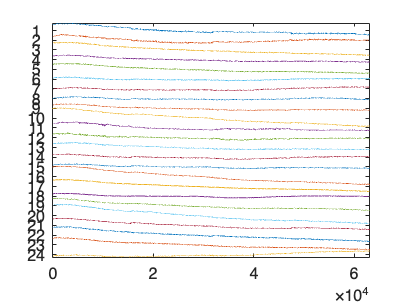

Participant 15 processed.


% Plotting settings for ALL CHANNELS – multiplying columns per rows must be
% equal to number of channels
columns = 4;
rows = 6;
grey = [0, 0, 0, 0.4];

% Pwelch/Spectrogram Parameters – ASSR/SSVEP and Alpha Block
n = 2; % seconds for window
nominal_fs = 250;  % default nominal_fs (will be overwritten by file info)
window = nominal_fs * n;
noverlap = window/2; % 50% overlap
nfft = 2^nextpow2(window); % next power of 2 after window size

% Epoch window and latency interval – estimated with the MBT jitterbox
latency = -8;       % ms, to account for system stimuli output latency
baseline_time = 200; % ms
analysis_time = 500; % ms

% ALPHA BLOCK parameters
alpha_t = 60;       % total time (seconds) for each eyes‑closed/open section
min_frequency = 5;  % for display purposes
max_frequency = 25;
alpha_lower = 8;    % lower bound of alpha (Hz)
alpha_upper = 12;   % upper bound of alpha (Hz)

% 3–tap, moving mean filter (if used)
smooth_filter = [1/3, 1/3, 1/3];

% Plots per figure
channels_figure = columns * rows;

% Number of participants to process
n_participants = 15;

%% Preallocate arrays for participant-level peak data (channels x participants)
% These will store, for each channel, the highest (peak) alpha power (in dB)
% separately for eyes‑closed and eyes‑open conditions.
peak_closed_all = NaN([], n_participants);  % size will be determined after n_channels is known
peak_open_all   = NaN([], n_participants); 

%% Loop through every participant

for participant = 1:n_participants
    fprintf('\nProcessing Participant %d...\n', participant);
    
    % --- File Selection and Data Loading ---
    [file_name, file_path] = uigetfile('*.xdf*', sprintf('Select the XDF file for participant %d', participant));
    if isequal(file_name, 0)
        warning('No file selected for participant %d. Skipping...', participant);
        continue;
    end
    full_file_path = fullfile(file_path, file_name);
    xdf_data = load_xdf(full_file_path);
    
    % --- Stream IDs ---
    marker_stream_id = input(sprintf('Enter marker stream id for participant %d: ', participant));
    data_stream_id   = input(sprintf('Enter data stream id for participant %d: ', participant));
    
    % --- Data Extraction from XDF Structure ---
    eeg_data            = xdf_data{data_stream_id}.time_series;
    eeg_data_timestamps = xdf_data{data_stream_id}.time_stamps;
    marker_stream       = xdf_data{marker_stream_id}.time_series;
    marker_timestamps   = xdf_data{marker_stream_id}.time_stamps;
    
    % Get sampling rate and number of channels from file info
    nominal_fs = floor(str2double(xdf_data{data_stream_id}.info.nominal_srate));
    fs         = xdf_data{data_stream_id}.segments.effective_srate;
    n_channels = str2double(xdf_data{data_stream_id}.info.channel_count);

    
    % (If this is the first participant, preallocate the arrays accordingly.)
    if participant == 1
        peak_closed_all = NaN(n_channels, n_participants);
        peak_open_all   = NaN(n_channels, n_participants);

        % Preallocate cell arrays for storing power spectrograms for each trial and participant
        ps_ec1_all = cell(n_channels, n_participants);  % Eyes-closed trial 1
        ps_eo1_all = cell(n_channels, n_participants);  % Eyes-open trial 1
        ps_ec2_all = cell(n_channels, n_participants);  % Eyes-closed trial 2
        ps_eo2_all = cell(n_channels, n_participants);  % Eyes-open trial 2

        % Preallocate arrays to store all trial data for each participant and channel
        peak_closed_all_trials = NaN(n_channels, n_participants, 2);  % 2 trials for each participant (Closed)
        peak_open_all_trials   = NaN(n_channels, n_participants, 2);
    end
    
    % Create channel labels based on device type.
    if n_channels == 1
        channelLabels = containers.Map('KeyType','single','ValueType','char');
        channelLabels(1) = 'In-Ear Single-Channel';
        channels = strings(n_channels, 1);
        keys = channelLabels.keys;
        for i = 1:n_channels
            channels(i) = channelLabels(keys{i});
        end
    elseif n_channels == 24
        channelLabels = containers.Map('KeyType','single','ValueType','char');
        channelLabels(1)  = 'Fp1';
        channelLabels(2)  = 'Fp2';
        channelLabels(3)  = 'F3';
        channelLabels(4)  = 'F4';
        channelLabels(5)  = 'C3';
        channelLabels(6)  = 'C4';
        channelLabels(7)  = 'P3';
        channelLabels(8)  = 'P4';
        channelLabels(9)  = 'O1';
        channelLabels(10) = 'O2';
        channelLabels(11) = 'F7';
        channelLabels(12) = 'F8';
        channelLabels(13) = 'T7';
        channelLabels(14) = 'T8';
        channelLabels(15) = 'P7';
        channelLabels(16) = 'P8';
        channelLabels(17) = 'Fz';
        channelLabels(18) = 'Cz';
        channelLabels(19) = 'Pz';
        channelLabels(20) = 'M1';
        channelLabels(21) = 'M2';
        channelLabels(22) = 'AFz';
        channelLabels(23) = 'CPz';
        channelLabels(24) = 'POz';
        channels = strings(n_channels, 1);
        keys = channelLabels.keys;
        for i = 1:n_channels
            channels(i) = channelLabels(keys{i});
        end
    else
        channels = strings(n_channels, 1);
        for i = 1:n_channels
            channels(i) = sprintf('Ch%d', i);
        end
    end
    
    figures = ceil(n_channels/channels_figure);
    
    %% Extract the Overall EEG Segment (defined by markers "alpha_start" and "alpha_end")
    start_marker = 'alpha_start';
    end_marker   = 'alpha_end';
    
    %% isue with P9 is here
    start_marker_index = find(strcmp(marker_stream, start_marker), 1);
    end_marker_index   = find(strcmp(marker_stream, end_marker), 1);
    
    start_time = marker_timestamps(start_marker_index);
    end_time   = marker_timestamps(end_marker_index);
    
    [~, start_index] = min(abs(eeg_data_timestamps - start_time));
    [~, end_index]   = min(abs(eeg_data_timestamps - end_time));
    
    data = eeg_data(:, start_index:end_index);
    data_timestamps = eeg_data_timestamps(start_index:end_index);

    % Gets stimuli or other markers and their timestamps for this paradigm
    markers = marker_stream(start_marker_index + 1:end_marker_index - 1);
    markers_timestamps = marker_timestamps(start_marker_index + 1:end_marker_index - 1);
    
%% Preprocessing: Filtering and Referencing

    fc_high = 1;    % Highpass cut-off
    fc_low  = 100;  % Lowpass cut-off
    
    data = double(data);
    Complot(data - mean(data, 2));  % Optional plot for quality check
    
    filtered_data  = zeros(size(data));
    processed_data = zeros(size(data));
    
    % Highpass Filtering
    [b, a] = butter(4, fc_high/(nominal_fs/2), 'high');
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, data(ch, :));
    end
    
    % Notch Filtering (50 Hz)
    f_notch = 50;
    Q       = 35;
    wo      = f_notch/(nominal_fs/2);
    bw      = wo/Q;
    [b, a] = iirnotch(wo, bw);
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, filtered_data(ch, :));
    end
    
    % Lowpass Filtering
    [b, a] = butter(4, fc_low/(nominal_fs/2), 'low');
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, filtered_data(ch, :));
    end
    processed_data = filtered_data;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Reference the data

    ref_channel = 14; % T8

    ref_data = filtered_data(ref_channel,:);

    for i = 1:n_channels
        if i == ref_channel
            continue
        else
            processed_data(i,:) = filtered_data(i,:) - ref_data;
        end
    end
    

    % Select and save the data for channel 13 (T7):
    channel_T7_data = processed_data(13, :);
    
    % Hold data for the current participant
    participant_data = struct();


    %% Data Length Correction for Eyes–Closed/Open Sections
    % (Assuming markers_timestamps is a vector with 8 elements for the events.)
    [~, start_index_ec1] = min(abs(data_timestamps - markers_timestamps(1)));
    [~, end_index_ec1]   = min(abs(data_timestamps - markers_timestamps(2)));
    [~, start_index_eo1] = min(abs(data_timestamps - markers_timestamps(3)));
    [~, end_index_eo1]   = min(abs(data_timestamps - markers_timestamps(4)));
    [~, start_index_ec2] = min(abs(data_timestamps - markers_timestamps(5)));
    [~, end_index_ec2]   = min(abs(data_timestamps - markers_timestamps(6)));
    [~, start_index_eo2] = min(abs(data_timestamps - markers_timestamps(7)));
    [~, end_index_eo2]   = min(abs(data_timestamps - markers_timestamps(8)));
    
    ec_data1 = processed_data(:, start_index_ec1:end_index_ec1);
    eo_data1 = processed_data(:, start_index_eo1:end_index_eo1);
    ec_data2 = processed_data(:, start_index_ec2:end_index_ec2);
    eo_data2 = processed_data(:, start_index_eo2:end_index_eo2);
    
    corrected_length = alpha_t * nominal_fs;
    % Trim each segment to the last 'corrected_length' samples
    ec_data1 = ec_data1(:, end - corrected_length + 1:end);
    eo_data1 = eo_data1(:, end - corrected_length + 1:end);
    ec_data2 = ec_data2(:, end - corrected_length + 1:end);
    eo_data2 = eo_data2(:, end - corrected_length + 1:end);
    
    % Replace any NaNs with zeros in each segment
    nan_rows = any(isnan(ec_data1), 2); ec_data1(nan_rows, :) = 0;
    nan_rows = any(isnan(eo_data1), 2); eo_data1(nan_rows, :) = 0;
    nan_rows = any(isnan(ec_data2), 2); ec_data2(nan_rows, :) = 0;
    nan_rows = any(isnan(eo_data2), 2); eo_data2(nan_rows, :) = 0;

    channel_T7_ec = [ec_data1(13,:),ec_data2(13,:)];
    channel_T7_eo = [eo_data1(13,:),eo_data2(13,:)];
    participant_data.channel_T7ec = channel_T7_ec;
    participant_data.channel_T7eo = channel_T7_eo;
    % Create the filename for saving the combined data of the current participant
    combined_filename = sprintf('Participant_%d_T7_refT8_AB.mat', participant);
    
    % Save the struct to a single .mat file
    save(combined_filename, 'participant_data');
    
    %% Compute Peak Alpha Power in the 8–12 Hz Band for Each Segment
    % For each channel, we compute the spectrogram for each segment, restrict to the
    % alpha band (8–12 Hz), and take the maximum (peak) value (in dB) over frequency and time.
    peak_ec1 = zeros(n_channels, 1);
    peak_eo1 = zeros(n_channels, 1);
    peak_ec2 = zeros(n_channels, 1);
    peak_eo2 = zeros(n_channels, 1);
    
    for ch = 1:(n_channels )
        % Compute spectrogram for each segment
        [~, f, ~, ps_ec1] = spectrogram(ec_data1(ch,:), window, noverlap, nfft, nominal_fs, 'power');
        [~, ~, ~, ps_eo1] = spectrogram(eo_data1(ch,:), window, noverlap, nfft, nominal_fs, 'power');
        [~, ~, ~, ps_ec2] = spectrogram(ec_data2(ch,:), window, noverlap, nfft, nominal_fs, 'power');
        [~, ~, ~, ps_eo2] = spectrogram(eo_data2(ch,:), window, noverlap, nfft, nominal_fs, 'power');
        

        % Define alpha indices based on the frequency vector f
        alpha_idx = (f >= alpha_lower) & (f <= alpha_upper);
        
        % Convert power to dB and restrict to the alpha band
        ps_ec1_alpha = pow2db(ps_ec1(alpha_idx, :));
        ps_eo1_alpha = pow2db(ps_eo1(alpha_idx, :));
        ps_ec2_alpha = pow2db(ps_ec2(alpha_idx, :));
        ps_eo2_alpha = pow2db(ps_eo2(alpha_idx, :));
        
        % Find the maximum (peak) value within each segment (over all frequency and time points)
        peak_ec1(ch) = max(ps_ec1_alpha(:));
        peak_eo1(ch) = max(ps_eo1_alpha(:));
        peak_ec2(ch) = max(ps_ec2_alpha(:));
        peak_eo2(ch) = max(ps_eo2_alpha(:));

        % Store these peak values for each trial (no averaging)
        peak_closed_all_trials(ch, participant, 1) = peak_ec1(ch);  % Trial 1 for Closed
        peak_open_all_trials(ch, participant, 1)   = peak_eo1(ch);  % Trial 1 for Open
        peak_closed_all_trials(ch, participant, 2) = peak_ec2(ch);  % Trial 2 for Closed
        peak_open_all_trials(ch, participant, 2)   = peak_eo2(ch);  % Trial 2 for Open
    end
    
    % Average the two eyes–closed peaks and the two eyes–open peaks for each channel
    peak_closed = (peak_ec1 + peak_ec2) / 2;
    peak_open   = (peak_eo1 + peak_eo2) / 2;
    
    % Store these peak values for this participant
    peak_closed_all(:, participant) = peak_closed;
    peak_open_all(:, participant)   = peak_open;
    
    fprintf('Participant %d processed.\n', participant);
end


%% Individual participant analysis
snr_participant = NaN(n_channels, n_participants);
std_participant = NaN(n_channels, n_participants);

for participant = 1 : n_participants
    for ch = 1 : (n_channels )
        snr_participant(ch,participant) = peak_closed_all(ch,participant) - peak_open_all(ch,participant);
        
        std_participant(ch,participant) = std([peak_closed_all(ch, participant), peak_open_all(ch, participant)]);
        
        closed_data = squeeze(peak_closed_all_trials(ch, participant, :)); % All trials for closed condition
        open_data = squeeze(peak_open_all_trials(ch, participant, :));     % All trials for open condition
    end
end


%% Grand Average Statistical Analysis Across Subjects
snr_ratio = NaN(n_channels, 1);
snr_std   = NaN(n_channels, 1);

% Find statistics for every channel
for ch = 1:n_channels
    % Extract data for the current channel (all participants)
    closed_vector = peak_closed_all(ch, :);  %
    open_vector   = peak_open_all(ch, :);    

    if numel(closed_vector) > 1 && numel(open_vector) > 1
        % Check normality of both
        [h_closed, p_closed] = swtest(closed_vector);  
        [h_open, p_open] = swtest(open_vector);        

        % Use paired t-test or Wilcoxon given normality
        if h_closed == 0 && h_open == 0  
            % Perform paired T-test for normal data
            [~, p_avg, ~, stats] = ttest(closed_vector, open_vector);
            disp(['Channel ' channels{ch} ' (T-test): p-value = ' num2str(p_avg)]);
        else  
            % Perform Wilcoxon Signed-Rank test for non-normal data
            [p_avg, ~] = signrank(closed_vector, open_vector);
            disp(['Channel ' channels{ch} ' (Wilcoxon Signed-Rank): p-value = ' num2str(p_avg)]);
        end 
    end
    
    % Compute the SNR ratio (mean difference) and its standard deviation
    diff_vals = closed_vector - open_vector;
    snr_ratio(ch) = mean(diff_vals);  
    fprintf('Mean SNR Ratio for channel %d: %.4f\n', ch, snr_ratio(ch));
    snr_std(ch) = std(diff_vals);    
    fprintf('Mean  STD for channel %d: %.4f\n', ch, snr_ratio(ch));
end

Channel Fp1 (T-test): p-value = 0.03606


Mean SNR Ratio for channel 1: 1.4834


Mean  STD for channel 1: 1.4834


Channel Fp2 (T-test): p-value = 0.052429


Mean SNR Ratio for channel 2: 1.3743


Mean  STD for channel 2: 1.3743


Channel F3 (Wilcoxon Signed-Rank): p-value = 0.00085449


Mean SNR Ratio for channel 3: 2.8086


Mean  STD for channel 3: 2.8086


Channel F4 (Wilcoxon Signed-Rank): p-value = 0.00061035


Mean SNR Ratio for channel 4: 3.0268


Mean  STD for channel 4: 3.0268


Channel C3 (Wilcoxon Signed-Rank): p-value = 6.1035e-05


Mean SNR Ratio for channel 5: 2.6118


Mean  STD for channel 5: 2.6118


Channel C4 (Wilcoxon Signed-Rank): p-value = 0.00085449


Mean SNR Ratio for channel 6: 2.2220


Mean  STD for channel 6: 2.2220


Channel P3 (T-test): p-value = 3.1302e-05


Mean SNR Ratio for channel 7: 5.4871


Mean  STD for channel 7: 5.4871


Channel P4 (Wilcoxon Signed-Rank): p-value = 6.1035e-05


Mean SNR Ratio for channel 8: 7.3915


Mean  STD for channel 8: 7.3915


Channel O1 (T-test): p-value = 1.6091e-05


Mean SNR Ratio for channel 9: 6.6050


Mean  STD for channel 9: 6.6050


Channel O2 (T-test): p-value = 1.2886e-05


Mean SNR Ratio for channel 10: 7.0330


Mean  STD for channel 10: 7.0330


Channel F7 (Wilcoxon Signed-Rank): p-value = 0.0053711


Mean SNR Ratio for channel 11: 2.0570


Mean  STD for channel 11: 2.0570


Channel F8 (Wilcoxon Signed-Rank): p-value = 0.00061035


Mean SNR Ratio for channel 12: 3.0194


Mean  STD for channel 12: 3.0194


Channel T7 (T-test): p-value = 0.011773


Mean SNR Ratio for channel 13: 2.2016


Mean  STD for channel 13: 2.2016


Channel T8 (Wilcoxon Signed-Rank): p-value = 0.00030518


Mean SNR Ratio for channel 14: 3.5580


Mean  STD for channel 14: 3.5580


Channel P7 (T-test): p-value = 5.3915e-06


Mean SNR Ratio for channel 15: 6.0786


Mean  STD for channel 15: 6.0786


Channel P8 (T-test): p-value = 5.4051e-07


Mean SNR Ratio for channel 16: 8.2836


Mean  STD for channel 16: 8.2836


Channel Fz (Wilcoxon Signed-Rank): p-value = 0.00018311


Mean SNR Ratio for channel 17: 3.3741


Mean  STD for channel 17: 3.3741


Channel Cz (T-test): p-value = 0.00018186


Mean SNR Ratio for channel 18: 3.5716


Mean  STD for channel 18: 3.5716


Channel Pz (T-test): p-value = 9.3905e-05


Mean SNR Ratio for channel 19: 5.9742


Mean  STD for channel 19: 5.9742


Channel M1 (T-test): p-value = 0.00031514


Mean SNR Ratio for channel 20: 2.4378


Mean  STD for channel 20: 2.4378


Channel M2 (T-test): p-value = 0.0016976


Mean SNR Ratio for channel 21: 2.9495


Mean  STD for channel 21: 2.9495


Channel AFz (Wilcoxon Signed-Rank): p-value = 0.0011597


Mean SNR Ratio for channel 22: 3.0577


Mean  STD for channel 22: 3.0577


Channel CPz (Wilcoxon Signed-Rank): p-value = 0.00030518


Mean SNR Ratio for channel 23: 4.1346


Mean  STD for channel 23: 4.1346


Channel POz (T-test): p-value = 3.8924e-05


Mean SNR Ratio for channel 24: 6.8790


Mean  STD for channel 24: 6.8790





% SNR values for each participant and each channel
disp('SNR values (dB) for each participant (per channel):');

SNR values (dB) for each participant (per channel):


for ch = 1 : (n_channels - 1)
    fprintf('Channel %d:\n', ch);  
    for participant = 1:n_participants
        fprintf('  Participant %d: SNR = %.4f\n', participant, snr_participant(ch, participant));
    end
end

Channel 1:


  Participant 1: SNR = 6.3688
  Participant 2: SNR = 3.4233
  Participant 3: SNR = 1.3355
  Participant 4: SNR = -0.7706
  Participant 5: SNR = -2.2037
  Participant 6: SNR = 3.4393
  Participant 7: SNR = 1.9790
  Participant 8: SNR = 2.7565
  Participant 9: SNR = 4.2820
  Participant 10: SNR = 2.5493
  Participant 11: SNR = 1.2009
  Participant 12: SNR = -0.9769
  Participant 13: SNR = -2.5574
  Participant 14: SNR = 1.5271
  Participant 15: SNR = -0.1021


Channel 2:


  Participant 1: SNR = 6.0929
  Participant 2: SNR = 3.2079
  Participant 3: SNR = 1.8717
  Participant 4: SNR = -0.8460
  Participant 5: SNR = -2.2542
  Participant 6: SNR = 3.5402
  Participant 7: SNR = 1.9206
  Participant 8: SNR = 2.3304
  Participant 9: SNR = 4.4310
  Participant 10: SNR = 3.0794
  Participant 11: SNR = 0.8272
  Participant 12: SNR = -0.8774
  Participant 13: SNR = -2.6078
  Participant 14: SNR = -0.7214
  Participant 15: SNR = 0.6203


Channel 3:


  Participant 1: SNR = 4.0922
  Participant 2: SNR = 3.4482
  Participant 3: SNR = 2.0747
  Participant 4: SNR = -0.4948
  Participant 5: SNR = -2.1900
  Participant 6: SNR = 4.2773
  Participant 7: SNR = 1.8434
  Participant 8: SNR = 3.0869
  Participant 9: SNR = 4.9887
  Participant 10: SNR = 2.7657
  Participant 11: SNR = 5.9201
  Participant 12: SNR = 3.9417
  Participant 13: SNR = 2.2394
  Participant 14: SNR = 5.5389
  Participant 15: SNR = 0.5961


Channel 4:


  Participant 1: SNR = 3.6421
  Participant 2: SNR = 2.8612
  Participant 3: SNR = 2.7652
  Participant 4: SNR = 0.7604
  Participant 5: SNR = -2.6154
  Participant 6: SNR = 4.7079
  Participant 7: SNR = 1.8503
  Participant 8: SNR = 3.3992
  Participant 9: SNR = 5.0268
  Participant 10: SNR = 4.5284
  Participant 11: SNR = 4.4860
  Participant 12: SNR = 3.8887
  Participant 13: SNR = 2.3535
  Participant 14: SNR = 6.5980
  Participant 15: SNR = 1.1504


Channel 5:


  Participant 1: SNR = 0.3639
  Participant 2: SNR = 0.0240
  Participant 3: SNR = 0.8926
  Participant 4: SNR = 0.3970
  Participant 5: SNR = 0.2462
  Participant 6: SNR = 3.8745
  Participant 7: SNR = 3.1338
  Participant 8: SNR = 4.5800
  Participant 9: SNR = 1.6053
  Participant 10: SNR = 0.5433
  Participant 11: SNR = 7.4727
  Participant 12: SNR = 2.8311
  Participant 13: SNR = 3.7074
  Participant 14: SNR = 8.6065
  Participant 15: SNR = 0.8984


Channel 6:


  Participant 1: SNR = 0.9420
  Participant 2: SNR = -1.1468
  Participant 3: SNR = 1.6970
  Participant 4: SNR = 2.4520
  Participant 5: SNR = -0.6903
  Participant 6: SNR = 3.1356
  Participant 7: SNR = 1.7600
  Participant 8: SNR = 3.2345
  Participant 9: SNR = 0.1747
  Participant 10: SNR = 2.5852
  Participant 11: SNR = 6.3679
  Participant 12: SNR = 3.6974
  Participant 13: SNR = 3.6897
  Participant 14: SNR = 3.6557
  Participant 15: SNR = 1.7755


Channel 7:


  Participant 1: SNR = 6.9687
  Participant 2: SNR = 3.1682
  Participant 3: SNR = 2.7819
  Participant 4: SNR = 0.8843
  Participant 5: SNR = 0.3363
  Participant 6: SNR = 3.7171
  Participant 7: SNR = 7.0423
  Participant 8: SNR = 9.2263
  Participant 9: SNR = 4.1109
  Participant 10: SNR = 3.2409
  Participant 11: SNR = 11.4288
  Participant 12: SNR = 6.6537
  Participant 13: SNR = 8.1714
  Participant 14: SNR = 11.4632
  Participant 15: SNR = 3.1117


Channel 8:


  Participant 1: SNR = 11.2282
  Participant 2: SNR = 2.3538
  Participant 3: SNR = 2.6534
  Participant 4: SNR = 3.6654
  Participant 5: SNR = 1.2536
  Participant 6: SNR = 8.4894
  Participant 7: SNR = 8.4625
  Participant 8: SNR = 11.5380
  Participant 9: SNR = 5.7248
  Participant 10: SNR = 7.3694
  Participant 11: SNR = 14.2358
  Participant 12: SNR = 12.2182
  Participant 13: SNR = 6.5424
  Participant 14: SNR = 11.2554
  Participant 15: SNR = 3.8821


Channel 9:


  Participant 1: SNR = 9.2791
  Participant 2: SNR = 3.1157
  Participant 3: SNR = 4.0703
  Participant 4: SNR = 2.5652
  Participant 5: SNR = -1.1485
  Participant 6: SNR = 6.4818
  Participant 7: SNR = 5.6137
  Participant 8: SNR = 8.7043
  Participant 9: SNR = 6.1749
  Participant 10: SNR = 7.8160
  Participant 11: SNR = 14.3737
  Participant 12: SNR = 11.5165
  Participant 13: SNR = 5.0190
  Participant 14: SNR = 11.1861
  Participant 15: SNR = 4.3069


Channel 10:


  Participant 1: SNR = 9.2741
  Participant 2: SNR = 2.4116
  Participant 3: SNR = 3.6137
  Participant 4: SNR = 2.0778
  Participant 5: SNR = -0.4549
  Participant 6: SNR = 10.7787
  Participant 7: SNR = 6.1420
  Participant 8: SNR = 6.7847
  Participant 9: SNR = 5.8532
  Participant 10: SNR = 11.6211
  Participant 11: SNR = 11.6893
  Participant 12: SNR = 13.1606
  Participant 13: SNR = 6.3805
  Participant 14: SNR = 11.5564
  Participant 15: SNR = 4.6059


Channel 11:


  Participant 1: SNR = 5.5305
  Participant 2: SNR = 2.7406
  Participant 3: SNR = 1.0621
  Participant 4: SNR = -0.8425
  Participant 5: SNR = -1.3805
  Participant 6: SNR = 3.6067
  Participant 7: SNR = 1.6908
  Participant 8: SNR = 3.6037
  Participant 9: SNR = 3.5794
  Participant 10: SNR = 1.8036
  Participant 11: SNR = 3.9695
  Participant 12: SNR = 0.9409
  Participant 13: SNR = -0.9563
  Participant 14: SNR = 5.6849
  Participant 15: SNR = -0.1778


Channel 12:


  Participant 1: SNR = 6.0592
  Participant 2: SNR = 4.0782
  Participant 3: SNR = 3.5741
  Participant 4: SNR = -0.0260
  Participant 5: SNR = -1.4352
  Participant 6: SNR = 6.4968
  Participant 7: SNR = 4.0553
  Participant 8: SNR = 2.8302
  Participant 9: SNR = 5.3872
  Participant 10: SNR = 4.6096
  Participant 11: SNR = 2.8522
  Participant 12: SNR = 3.4991
  Participant 13: SNR = 0.9324
  Participant 14: SNR = 1.8270
  Participant 15: SNR = 0.5510


Channel 13:


  Participant 1: SNR = 3.5047
  Participant 2: SNR = 3.8171
  Participant 3: SNR = 4.5339
  Participant 4: SNR = -2.6615
  Participant 5: SNR = -1.5805
  Participant 6: SNR = 4.2145
  Participant 7: SNR = 1.5910
  Participant 8: SNR = 4.1059
  Participant 9: SNR = 3.5060
  Participant 10: SNR = 0.0631
  Participant 11: SNR = 3.2513
  Participant 12: SNR = 3.1900
  Participant 13: SNR = -1.6502
  Participant 14: SNR = 7.9757
  Participant 15: SNR = -0.8362


Channel 14:


  Participant 1: SNR = 2.9998
  Participant 2: SNR = 1.3111
  Participant 3: SNR = 2.8329
  Participant 4: SNR = 0.8186
  Participant 5: SNR = -1.9304
  Participant 6: SNR = 4.7062
  Participant 7: SNR = 3.3562
  Participant 8: SNR = 4.3385
  Participant 9: SNR = 5.1702
  Participant 10: SNR = 3.2140
  Participant 11: SNR = 6.3966
  Participant 12: SNR = 3.7990
  Participant 13: SNR = 3.2944
  Participant 14: SNR = 9.2960
  Participant 15: SNR = 3.7670


Channel 15:


  Participant 1: SNR = 6.4002
  Participant 2: SNR = 2.9726
  Participant 3: SNR = 5.0802
  Participant 4: SNR = 0.7682
  Participant 5: SNR = 0.6514
  Participant 6: SNR = 4.6908
  Participant 7: SNR = 7.3993
  Participant 8: SNR = 9.1517
  Participant 9: SNR = 6.1169
  Participant 10: SNR = 5.0207
  Participant 11: SNR = 11.7483
  Participant 12: SNR = 6.6010
  Participant 13: SNR = 6.2835
  Participant 14: SNR = 12.3312
  Participant 15: SNR = 5.9630


Channel 16:


  Participant 1: SNR = 7.7818
  Participant 2: SNR = 3.0630
  Participant 3: SNR = 4.3318
  Participant 4: SNR = 4.4688
  Participant 5: SNR = 2.1900
  Participant 6: SNR = 14.0819
  Participant 7: SNR = 8.9017
  Participant 8: SNR = 8.0809
  Participant 9: SNR = 7.7614
  Participant 10: SNR = 10.6812
  Participant 11: SNR = 13.2282
  Participant 12: SNR = 13.5600
  Participant 13: SNR = 6.9615
  Participant 14: SNR = 9.6911
  Participant 15: SNR = 9.4701


Channel 17:


  Participant 1: SNR = 3.9466
  Participant 2: SNR = 2.5783
  Participant 3: SNR = 2.3279
  Participant 4: SNR = 0.1697
  Participant 5: SNR = -1.8867
  Participant 6: SNR = 4.4464
  Participant 7: SNR = 2.2592
  Participant 8: SNR = 4.1146
  Participant 9: SNR = 6.0748
  Participant 10: SNR = 3.7352
  Participant 11: SNR = 5.4160
  Participant 12: SNR = 4.1538
  Participant 13: SNR = 2.5891
  Participant 14: SNR = 8.7859
  Participant 15: SNR = 1.8998


Channel 18:


  Participant 1: SNR = 2.1568
  Participant 2: SNR = -0.6300
  Participant 3: SNR = 3.3068
  Participant 4: SNR = 0.7189
  Participant 5: SNR = 0.2476
  Participant 6: SNR = 4.2708
  Participant 7: SNR = 2.6185
  Participant 8: SNR = 5.3872
  Participant 9: SNR = 3.5006
  Participant 10: SNR = 3.2398
  Participant 11: SNR = 8.4634
  Participant 12: SNR = 3.8931
  Participant 13: SNR = 3.5154
  Participant 14: SNR = 9.7116
  Participant 15: SNR = 3.1738


Channel 19:


  Participant 1: SNR = 9.2702
  Participant 2: SNR = -0.4184
  Participant 3: SNR = 2.0507
  Participant 4: SNR = 4.3219
  Participant 5: SNR = -0.6362
  Participant 6: SNR = 5.4525
  Participant 7: SNR = 6.1234
  Participant 8: SNR = 9.9060
  Participant 9: SNR = 4.5699
  Participant 10: SNR = 2.9755
  Participant 11: SNR = 13.7928
  Participant 12: SNR = 10.4212
  Participant 13: SNR = 6.4662
  Participant 14: SNR = 11.5390
  Participant 15: SNR = 3.7788


Channel 20:


  Participant 1: SNR = 3.6851
  Participant 2: SNR = 2.6418
  Participant 3: SNR = 2.8968
  Participant 4: SNR = 0.1950
  Participant 5: SNR = -1.5216
  Participant 6: SNR = 5.4790
  Participant 7: SNR = 2.1897
  Participant 8: SNR = 3.4207
  Participant 9: SNR = 3.0372
  Participant 10: SNR = 0.2559
  Participant 11: SNR = 5.4533
  Participant 12: SNR = 2.0697
  Participant 13: SNR = 2.0362
  Participant 14: SNR = 4.3868
  Participant 15: SNR = 0.3409


Channel 21:


  Participant 1: SNR = -0.1526
  Participant 2: SNR = 1.9168
  Participant 3: SNR = 1.0227
  Participant 4: SNR = 1.4819
  Participant 5: SNR = -1.8097
  Participant 6: SNR = 6.7231
  Participant 7: SNR = 2.6079
  Participant 8: SNR = -0.1818
  Participant 9: SNR = 3.4716
  Participant 10: SNR = 7.0051
  Participant 11: SNR = 8.3247
  Participant 12: SNR = 5.2584
  Participant 13: SNR = 2.1261
  Participant 14: SNR = 5.0687
  Participant 15: SNR = 1.3791


Channel 22:


  Participant 1: SNR = 5.2919
  Participant 2: SNR = 3.3554
  Participant 3: SNR = 1.9092
  Participant 4: SNR = -0.2736
  Participant 5: SNR = -2.3224
  Participant 6: SNR = 4.1239
  Participant 7: SNR = 1.7084
  Participant 8: SNR = 4.4970
  Participant 9: SNR = 5.5240
  Participant 10: SNR = 3.4559
  Participant 11: SNR = 4.1098
  Participant 12: SNR = 4.1622
  Participant 13: SNR = 0.5721
  Participant 14: SNR = 7.9377
  Participant 15: SNR = 1.8148


Channel 23:


  Participant 1: SNR = 5.0452
  Participant 2: SNR = -0.8086
  Participant 3: SNR = 2.8152
  Participant 4: SNR = 2.5050
  Participant 5: SNR = -0.3085
  Participant 6: SNR = 4.1296
  Participant 7: SNR = 2.4973
  Participant 8: SNR = 6.8741
  Participant 9: SNR = 2.2594
  Participant 10: SNR = 2.9347
  Participant 11: SNR = 10.4809
  Participant 12: SNR = 6.2171
  Participant 13: SNR = 4.3900
  Participant 14: SNR = 10.9446
  Participant 15: SNR = 2.0429



% STD values for each participant and each channel
disp('Standard Deviation (dB) values for each participant (per channel):');

Standard Deviation (dB) values for each participant (per channel):


for ch = 1 : (n_channels - 1)
    fprintf('Channel %d:\n', ch);  
    for participant = 1:n_participants
        fprintf('  Participant %d: STD = %.4f\n', participant, std_participant(ch, participant));
    end
end

Channel 1:


  Participant 1: STD = 4.5034
  Participant 2: STD = 2.4206
  Participant 3: STD = 0.9443
  Participant 4: STD = 0.5449
  Participant 5: STD = 1.5583
  Participant 6: STD = 2.4320
  Participant 7: STD = 1.3994
  Participant 8: STD = 1.9491
  Participant 9: STD = 3.0278
  Participant 10: STD = 1.8026
  Participant 11: STD = 0.8492
  Participant 12: STD = 0.6907
  Participant 13: STD = 1.8083
  Participant 14: STD = 1.0798
  Participant 15: STD = 0.0722


Channel 2:


  Participant 1: STD = 4.3083
  Participant 2: STD = 2.2683
  Participant 3: STD = 1.3235
  Participant 4: STD = 0.5982
  Participant 5: STD = 1.5940
  Participant 6: STD = 2.5033
  Participant 7: STD = 1.3581
  Participant 8: STD = 1.6479
  Participant 9: STD = 3.1332
  Participant 10: STD = 2.1774
  Participant 11: STD = 0.5849
  Participant 12: STD = 0.6204
  Participant 13: STD = 1.8440
  Participant 14: STD = 0.5101
  Participant 15: STD = 0.4386


Channel 3:


  Participant 1: STD = 2.8936
  Participant 2: STD = 2.4382
  Participant 3: STD = 1.4671
  Participant 4: STD = 0.3499
  Participant 5: STD = 1.5485
  Participant 6: STD = 3.0245
  Participant 7: STD = 1.3035
  Participant 8: STD = 2.1828
  Participant 9: STD = 3.5275
  Participant 10: STD = 1.9557
  Participant 11: STD = 4.1861
  Participant 12: STD = 2.7872
  Participant 13: STD = 1.5835
  Participant 14: STD = 3.9166
  Participant 15: STD = 0.4215


Channel 4:


  Participant 1: STD = 2.5753
  Participant 2: STD = 2.0232
  Participant 3: STD = 1.9553
  Participant 4: STD = 0.5377
  Participant 5: STD = 1.8494
  Participant 6: STD = 3.3290
  Participant 7: STD = 1.3084
  Participant 8: STD = 2.4036
  Participant 9: STD = 3.5545
  Participant 10: STD = 3.2021
  Participant 11: STD = 3.1721
  Participant 12: STD = 2.7497
  Participant 13: STD = 1.6642
  Participant 14: STD = 4.6655
  Participant 15: STD = 0.8134


Channel 5:


  Participant 1: STD = 0.2573
  Participant 2: STD = 0.0170
  Participant 3: STD = 0.6312
  Participant 4: STD = 0.2807
  Participant 5: STD = 0.1741
  Participant 6: STD = 2.7397
  Participant 7: STD = 2.2159
  Participant 8: STD = 3.2385
  Participant 9: STD = 1.1351
  Participant 10: STD = 0.3842
  Participant 11: STD = 5.2840
  Participant 12: STD = 2.0019
  Participant 13: STD = 2.6215
  Participant 14: STD = 6.0857
  Participant 15: STD = 0.6353


Channel 6:


  Participant 1: STD = 0.6661
  Participant 2: STD = 0.8109
  Participant 3: STD = 1.2000
  Participant 4: STD = 1.7338
  Participant 5: STD = 0.4881
  Participant 6: STD = 2.2172
  Participant 7: STD = 1.2445
  Participant 8: STD = 2.2871
  Participant 9: STD = 0.1236
  Participant 10: STD = 1.8280
  Participant 11: STD = 4.5028
  Participant 12: STD = 2.6145
  Participant 13: STD = 2.6090
  Participant 14: STD = 2.5850
  Participant 15: STD = 1.2555


Channel 7:


  Participant 1: STD = 4.9276
  Participant 2: STD = 2.2402
  Participant 3: STD = 1.9671
  Participant 4: STD = 0.6253
  Participant 5: STD = 0.2378
  Participant 6: STD = 2.6284
  Participant 7: STD = 4.9797
  Participant 8: STD = 6.5240
  Participant 9: STD = 2.9069
  Participant 10: STD = 2.2917
  Participant 11: STD = 8.0814
  Participant 12: STD = 4.7049
  Participant 13: STD = 5.7781
  Participant 14: STD = 8.1057
  Participant 15: STD = 2.2003


Channel 8:


  Participant 1: STD = 7.9395
  Participant 2: STD = 1.6644
  Participant 3: STD = 1.8762
  Participant 4: STD = 2.5919
  Participant 5: STD = 0.8865
  Participant 6: STD = 6.0029
  Participant 7: STD = 5.9839
  Participant 8: STD = 8.1586
  Participant 9: STD = 4.0480
  Participant 10: STD = 5.2109
  Participant 11: STD = 10.0662
  Participant 12: STD = 8.6396
  Participant 13: STD = 4.6262
  Participant 14: STD = 7.9588
  Participant 15: STD = 2.7451


Channel 9:


  Participant 1: STD = 6.5613
  Participant 2: STD = 2.2032
  Participant 3: STD = 2.8782
  Participant 4: STD = 1.8139
  Participant 5: STD = 0.8121
  Participant 6: STD = 4.5833
  Participant 7: STD = 3.9695
  Participant 8: STD = 6.1548
  Participant 9: STD = 4.3663
  Participant 10: STD = 5.5267
  Participant 11: STD = 10.1637
  Participant 12: STD = 8.1434
  Participant 13: STD = 3.5489
  Participant 14: STD = 7.9097
  Participant 15: STD = 3.0455


Channel 10:


  Participant 1: STD = 6.5578
  Participant 2: STD = 1.7053
  Participant 3: STD = 2.5553
  Participant 4: STD = 1.4692
  Participant 5: STD = 0.3216
  Participant 6: STD = 7.6217
  Participant 7: STD = 4.3431
  Participant 8: STD = 4.7975
  Participant 9: STD = 4.1389
  Participant 10: STD = 8.2174
  Participant 11: STD = 8.2656
  Participant 12: STD = 9.3059
  Participant 13: STD = 4.5117
  Participant 14: STD = 8.1716
  Participant 15: STD = 3.2569


Channel 11:


  Participant 1: STD = 3.9106
  Participant 2: STD = 1.9379
  Participant 3: STD = 0.7510
  Participant 4: STD = 0.5957
  Participant 5: STD = 0.9762
  Participant 6: STD = 2.5503
  Participant 7: STD = 1.1956
  Participant 8: STD = 2.5482
  Participant 9: STD = 2.5310
  Participant 10: STD = 1.2753
  Participant 11: STD = 2.8069
  Participant 12: STD = 0.6653
  Participant 13: STD = 0.6762
  Participant 14: STD = 4.0198
  Participant 15: STD = 0.1257


Channel 12:


  Participant 1: STD = 4.2845
  Participant 2: STD = 2.8838
  Participant 3: STD = 2.5273
  Participant 4: STD = 0.0184
  Participant 5: STD = 1.0148
  Participant 6: STD = 4.5939
  Participant 7: STD = 2.8675
  Participant 8: STD = 2.0013
  Participant 9: STD = 3.8093
  Participant 10: STD = 3.2595
  Participant 11: STD = 2.0168
  Participant 12: STD = 2.4743
  Participant 13: STD = 0.6593
  Participant 14: STD = 1.2919
  Participant 15: STD = 0.3896


Channel 13:


  Participant 1: STD = 2.4782
  Participant 2: STD = 2.6991
  Participant 3: STD = 3.2059
  Participant 4: STD = 1.8820
  Participant 5: STD = 1.1176
  Participant 6: STD = 2.9801
  Participant 7: STD = 1.1250
  Participant 8: STD = 2.9033
  Participant 9: STD = 2.4791
  Participant 10: STD = 0.0446
  Participant 11: STD = 2.2990
  Participant 12: STD = 2.2557
  Participant 13: STD = 1.1669
  Participant 14: STD = 5.6397
  Participant 15: STD = 0.5913


Channel 14:


  Participant 1: STD = 2.1212
  Participant 2: STD = 0.9271
  Participant 3: STD = 2.0032
  Participant 4: STD = 0.5788
  Participant 5: STD = 1.3650
  Participant 6: STD = 3.3278
  Participant 7: STD = 2.3732
  Participant 8: STD = 3.0678
  Participant 9: STD = 3.6559
  Participant 10: STD = 2.2726
  Participant 11: STD = 4.5230
  Participant 12: STD = 2.6863
  Participant 13: STD = 2.3295
  Participant 14: STD = 6.5733
  Participant 15: STD = 2.6637


Channel 15:


  Participant 1: STD = 4.5256
  Participant 2: STD = 2.1019
  Participant 3: STD = 3.5923
  Participant 4: STD = 0.5432
  Participant 5: STD = 0.4606
  Participant 6: STD = 3.3169
  Participant 7: STD = 5.2321
  Participant 8: STD = 6.4712
  Participant 9: STD = 4.3253
  Participant 10: STD = 3.5502
  Participant 11: STD = 8.3073
  Participant 12: STD = 4.6676
  Participant 13: STD = 4.4431
  Participant 14: STD = 8.7194
  Participant 15: STD = 4.2165


Channel 16:


  Participant 1: STD = 5.5026
  Participant 2: STD = 2.1659
  Participant 3: STD = 3.0631
  Participant 4: STD = 3.1599
  Participant 5: STD = 1.5486
  Participant 6: STD = 9.9574
  Participant 7: STD = 6.2945
  Participant 8: STD = 5.7141
  Participant 9: STD = 5.4882
  Participant 10: STD = 7.5528
  Participant 11: STD = 9.3537
  Participant 12: STD = 9.5884
  Participant 13: STD = 4.9225
  Participant 14: STD = 6.8526
  Participant 15: STD = 6.6963


Channel 17:


  Participant 1: STD = 2.7907
  Participant 2: STD = 1.8232
  Participant 3: STD = 1.6461
  Participant 4: STD = 0.1200
  Participant 5: STD = 1.3341
  Participant 6: STD = 3.1441
  Participant 7: STD = 1.5975
  Participant 8: STD = 2.9095
  Participant 9: STD = 4.2956
  Participant 10: STD = 2.6412
  Participant 11: STD = 3.8297
  Participant 12: STD = 2.9372
  Participant 13: STD = 1.8308
  Participant 14: STD = 6.2126
  Participant 15: STD = 1.3434


Channel 18:


  Participant 1: STD = 1.5251
  Participant 2: STD = 0.4455
  Participant 3: STD = 2.3383
  Participant 4: STD = 0.5083
  Participant 5: STD = 0.1751
  Participant 6: STD = 3.0199
  Participant 7: STD = 1.8515
  Participant 8: STD = 3.8093
  Participant 9: STD = 2.4753
  Participant 10: STD = 2.2909
  Participant 11: STD = 5.9845
  Participant 12: STD = 2.7529
  Participant 13: STD = 2.4858
  Participant 14: STD = 6.8671
  Participant 15: STD = 2.2442


Channel 19:


  Participant 1: STD = 6.5550
  Participant 2: STD = 0.2958
  Participant 3: STD = 1.4501
  Participant 4: STD = 3.0561
  Participant 5: STD = 0.4499
  Participant 6: STD = 3.8555
  Participant 7: STD = 4.3299
  Participant 8: STD = 7.0046
  Participant 9: STD = 3.2314
  Participant 10: STD = 2.1040
  Participant 11: STD = 9.7530
  Participant 12: STD = 7.3689
  Participant 13: STD = 4.5723
  Participant 14: STD = 8.1593
  Participant 15: STD = 2.6720


Channel 20:


  Participant 1: STD = 2.6057
  Participant 2: STD = 1.8680
  Participant 3: STD = 2.0483
  Participant 4: STD = 0.1379
  Participant 5: STD = 1.0759
  Participant 6: STD = 3.8743
  Participant 7: STD = 1.5483
  Participant 8: STD = 2.4188
  Participant 9: STD = 2.1476
  Participant 10: STD = 0.1810
  Participant 11: STD = 3.8561
  Participant 12: STD = 1.4635
  Participant 13: STD = 1.4398
  Participant 14: STD = 3.1019
  Participant 15: STD = 0.2410


Channel 21:


  Participant 1: STD = 0.1079
  Participant 2: STD = 1.3553
  Participant 3: STD = 0.7231
  Participant 4: STD = 1.0478
  Participant 5: STD = 1.2797
  Participant 6: STD = 4.7539
  Participant 7: STD = 1.8440
  Participant 8: STD = 0.1286
  Participant 9: STD = 2.4548
  Participant 10: STD = 4.9534
  Participant 11: STD = 5.8865
  Participant 12: STD = 3.7183
  Participant 13: STD = 1.5034
  Participant 14: STD = 3.5841
  Participant 15: STD = 0.9752


Channel 22:


  Participant 1: STD = 3.7420
  Participant 2: STD = 2.3727
  Participant 3: STD = 1.3500
  Participant 4: STD = 0.1935
  Participant 5: STD = 1.6422
  Participant 6: STD = 2.9160
  Participant 7: STD = 1.2080
  Participant 8: STD = 3.1799
  Participant 9: STD = 3.9060
  Participant 10: STD = 2.4437
  Participant 11: STD = 2.9060
  Participant 12: STD = 2.9431
  Participant 13: STD = 0.4045
  Participant 14: STD = 5.6128
  Participant 15: STD = 1.2833


Channel 23:


  Participant 1: STD = 3.5675
  Participant 2: STD = 0.5717
  Participant 3: STD = 1.9907
  Participant 4: STD = 1.7713
  Participant 5: STD = 0.2181
  Participant 6: STD = 2.9201
  Participant 7: STD = 1.7659
  Participant 8: STD = 4.8607
  Participant 9: STD = 1.5976
  Participant 10: STD = 2.0751
  Participant 11: STD = 7.4111
  Participant 12: STD = 4.3962
  Participant 13: STD = 3.1042
  Participant 14: STD = 7.7390
  Participant 15: STD = 1.4446


## Section 3: Ear EEG Preprocessing

% Plotting settings for ALL CHANNELS – multiplying columns per rows must be
% equal to number of channels
columns = 4;
rows = 6;
grey = [0, 0, 0, 0.4];

% Pwelch/Spectrogram Parameters – ASSR/SSVEP and Alpha Block
n = 2; % seconds for window
nominal_fs = 250;  % default nominal_fs (will be overwritten by file info)
window = nominal_fs * n;
noverlap = window/2; % 50% overlap
nfft = 2^nextpow2(window); % next power of 2 after window size

% Epoch window and latency interval – estimated with the MBT jitterbox
latency = -8;       % ms, to account for system stimuli output latency
baseline_time = 200; % ms
analysis_time = 500; % ms

% ALPHA BLOCK parameters
alpha_t = 60;       % total time (seconds) for each eyes‑closed/open section
min_frequency = 5;  % for display purposes
max_frequency = 25;
alpha_lower = 8;    % lower bound of alpha (Hz)
alpha_upper = 12;   % upper bound of alpha (Hz)

% 3–tap, moving mean filter (if used)
smooth_filter = [1/3, 1/3, 1/3];

% Plots per figure
channels_figure = columns * rows;

% Number of participants to process
n_participants = 1;

%% Preallocate arrays for participant-level peak data (channels x participants)
% These will store, for each channel, the highest (peak) alpha power (in dB)
% separately for eyes‑closed and eyes‑open conditions.
peak_closed_all = NaN([], n_participants);  % size will be determined after n_channels is known
peak_open_all   = NaN([], n_participants); 

%% Loop through every participant

for participant = 1:n_participants
    fprintf('\nProcessing Participant %d...\n', participant);
    
    % --- File Selection and Data Loading ---
    [file_name, file_path] = uigetfile('*.xdf*', sprintf('Select the XDF file for participant %d', participant));
    if isequal(file_name, 0)
        warning('No file selected for participant %d. Skipping...', participant);
        continue;
    end
    full_file_path = fullfile(file_path, file_name);
    xdf_data = load_xdf(full_file_path);
    
    % --- Stream IDs ---
    marker_stream_id = input(sprintf('Enter marker stream id for participant %d: ', participant));
    data_stream_id   = input(sprintf('Enter data stream id for participant %d: ', participant));
    
    % --- Data Extraction from XDF Structure ---
    eeg_data            = xdf_data{data_stream_id}.time_series;
    eeg_data_timestamps = xdf_data{data_stream_id}.time_stamps;
    marker_stream       = xdf_data{marker_stream_id}.time_series;
    marker_timestamps   = xdf_data{marker_stream_id}.time_stamps;
    
    % Get sampling rate and number of channels from file info
    nominal_fs = floor(str2double(xdf_data{data_stream_id}.info.nominal_srate));
    fs         = xdf_data{data_stream_id}.segments.effective_srate;
    n_channels = str2double(xdf_data{data_stream_id}.info.channel_count);

    
    % (If this is the first participant, preallocate the arrays accordingly.)
    if participant == 1
        peak_closed_all = NaN(n_channels, n_participants);
        peak_open_all   = NaN(n_channels, n_participants);

        % Preallocate cell arrays for storing power spectrograms for each trial and participant
        ps_ec1_all = cell(n_channels, n_participants);  % Eyes-closed trial 1
        ps_eo1_all = cell(n_channels, n_participants);  % Eyes-open trial 1
        ps_ec2_all = cell(n_channels, n_participants);  % Eyes-closed trial 2
        ps_eo2_all = cell(n_channels, n_participants);  % Eyes-open trial 2

        % Preallocate arrays to store all trial data for each participant and channel
        peak_closed_all_trials = NaN(n_channels, n_participants, 2);  % 2 trials for each participant (Closed)
        peak_open_all_trials   = NaN(n_channels, n_participants, 2);
    end
    
    % Create channel labels based on device type.
    if n_channels == 1
        channelLabels = containers.Map('KeyType','single','ValueType','char');
        channelLabels(1) = 'In-Ear Single-Channel';
        channels = strings(n_channels, 1);
        keys = channelLabels.keys;
        for i = 1:n_channels
            channels(i) = channelLabels(keys{i});
        end
    elseif n_channels == 24
        channelLabels = containers.Map('KeyType','single','ValueType','char');
        channelLabels(1)  = 'Fp1';
        channelLabels(2)  = 'Fp2';
        channelLabels(3)  = 'F3';
        channelLabels(4)  = 'F4';
        channelLabels(5)  = 'C3';
        channelLabels(6)  = 'C4';
        channelLabels(7)  = 'P3';
        channelLabels(8)  = 'P4';
        channelLabels(9)  = 'O1';
        channelLabels(10) = 'O2';
        channelLabels(11) = 'F7';
        channelLabels(12) = 'F8';
        channelLabels(13) = 'T7';
        channelLabels(14) = 'T8';
        channelLabels(15) = 'P7';
        channelLabels(16) = 'P8';
        channelLabels(17) = 'Fz';
        channelLabels(18) = 'Cz';
        channelLabels(19) = 'Pz';
        channelLabels(20) = 'M1';
        channelLabels(21) = 'M2';
        channelLabels(22) = 'AFz';
        channelLabels(23) = 'CPz';
        channelLabels(24) = 'POz';
        channels = strings(n_channels, 1);
        keys = channelLabels.keys;
        for i = 1:n_channels
            channels(i) = channelLabels(keys{i});
        end
    else
        channels = strings(n_channels, 1);
        for i = 1:n_channels
            channels(i) = sprintf('Ch%d', i);
        end
    end
    
    figures = ceil(n_channels/channels_figure);
    
    %% Extract the Overall EEG Segment (defined by markers "alpha_start" and "alpha_end")
    start_marker = 'alpha_start';
    end_marker   = 'alpha_end';
    
    %% isue with P9 is here
    start_marker_index = find(strcmp(marker_stream, start_marker), 1);
    end_marker_index   = find(strcmp(marker_stream, end_marker), 1);
    
    start_time = marker_timestamps(start_marker_index);
    end_time   = marker_timestamps(end_marker_index);
    
    [~, start_index] = min(abs(eeg_data_timestamps - start_time));
    [~, end_index]   = min(abs(eeg_data_timestamps - end_time));
    
    data = eeg_data(:, start_index:end_index);
    data_timestamps = eeg_data_timestamps(start_index:end_index);

    % Gets stimuli or other markers and their timestamps for this paradigm
    markers = marker_stream(start_marker_index + 1:end_marker_index - 1);
    markers_timestamps = marker_timestamps(start_marker_index + 1:end_marker_index - 1);
    
    %% Preprocessing: Filtering and Referencing

    fc_high = 1;    % Highpass cut-off
    fc_low  = 100;  % Lowpass cut-off
    
    data = double(data);
    Complot(data - mean(data, 2));  % Optional plot for quality check
    
    filtered_data  = zeros(size(data));
    processed_data = zeros(size(data));
    
    % Highpass Filtering
    [b, a] = butter(4, fc_high/(nominal_fs/2), 'high');
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, data(ch, :));
    end
    processed_data = filtered_data;
    
    % Notch Filtering (50 Hz)
    f_notch = 50;
    Q       = 35;
    wo      = f_notch/(nominal_fs/2);
    bw      = wo/Q;
    [b, a] = iirnotch(wo, bw);
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, filtered_data(ch, :));
    end
    processed_data = filtered_data;
    
    % Lowpass Filtering
    [b, a] = butter(4, fc_low/(nominal_fs/2), 'low');
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, filtered_data(ch, :));
    end
    processed_data = filtered_data;

    % Keep channel data
    ear_data = processed_data(1, :);
    
    % Hold data for the current participant
    participant_data = struct();
    participant_data.ear = ear_data;
    
    %% Data Length Correction for Eyes–Closed/Open Sections
    % (Assuming markers_timestamps is a vector with 8 elements for the events.)
    [~, start_index_ec1] = min(abs(data_timestamps - markers_timestamps(1)));
    [~, end_index_ec1]   = min(abs(data_timestamps - markers_timestamps(2)));
    [~, start_index_eo1] = min(abs(data_timestamps - markers_timestamps(3)));
    [~, end_index_eo1]   = min(abs(data_timestamps - markers_timestamps(4)));
    [~, start_index_ec2] = min(abs(data_timestamps - markers_timestamps(5)));
    [~, end_index_ec2]   = min(abs(data_timestamps - markers_timestamps(6)));
    [~, start_index_eo2] = min(abs(data_timestamps - markers_timestamps(7)));
    [~, end_index_eo2]   = min(abs(data_timestamps - markers_timestamps(8)));
    
    ec_data1 = processed_data(:, start_index_ec1:end_index_ec1);
    eo_data1 = processed_data(:, start_index_eo1:end_index_eo1);
    ec_data2 = processed_data(:, start_index_ec2:end_index_ec2);
    eo_data2 = processed_data(:, start_index_eo2:end_index_eo2);
    
    corrected_length = alpha_t * nominal_fs;
    % Trim each segment to the last 'corrected_length' samples
    ec_data1 = ec_data1(:, end - corrected_length + 1:end);
    eo_data1 = eo_data1(:, end - corrected_length + 1:end);
    ec_data2 = ec_data2(:, end - corrected_length + 1:end);
    eo_data2 = eo_data2(:, end - corrected_length + 1:end);
    
    % Replace any NaNs with zeros in each segment
    nan_rows = any(isnan(ec_data1), 2); ec_data1(nan_rows, :) = 0;
    nan_rows = any(isnan(eo_data1), 2); eo_data1(nan_rows, :) = 0;
    nan_rows = any(isnan(ec_data2), 2); ec_data2(nan_rows, :) = 0;
    nan_rows = any(isnan(eo_data2), 2); eo_data2(nan_rows, :) = 0;

    ear_ec = [ec_data1(1,:),ec_data2(1,:)];
    ear_eo = [eo_data1(1,:),eo_data2(1,:)];
    participant_data.ear_ec = ear_ec;
    participant_data.ear_eo = ear_eo;
    
    % Save data of participant
    combined_filename = sprintf('Participant_%d_ear_AB.mat');
    save(combined_filename, 'participant_data');
    
    %% Compute Peak Alpha Power in the 8–12 Hz Band for Each Segment
    % For each channel, we compute the spectrogram for each segment, restrict to the
    % alpha band (8–12 Hz), and take the maximum (peak) value (in dB) over frequency and time.
    peak_ec1 = zeros(n_channels, 1);
    peak_eo1 = zeros(n_channels, 1);
    peak_ec2 = zeros(n_channels, 1);
    peak_eo2 = zeros(n_channels, 1);
    

    % Compute spectrogram for each segment
    [~, f, ~, ps_ec1] = spectrogram(ec_data1(ch,:), window, noverlap, nfft, nominal_fs, 'power');
    [~, ~, ~, ps_eo1] = spectrogram(eo_data1(ch,:), window, noverlap, nfft, nominal_fs, 'power');
    [~, ~, ~, ps_ec2] = spectrogram(ec_data2(ch,:), window, noverlap, nfft, nominal_fs, 'power');
    [~, ~, ~, ps_eo2] = spectrogram(eo_data2(ch,:), window, noverlap, nfft, nominal_fs, 'power');
        

    % Define alpha indices based on the frequency vector f
    alpha_idx = (f >= alpha_lower) & (f <= alpha_upper);
        
    % Convert power to dB and restrict to the alpha band
    ps_ec1_alpha = pow2db(ps_ec1(alpha_idx, :));
    ps_eo1_alpha = pow2db(ps_eo1(alpha_idx, :));
    ps_ec2_alpha = pow2db(ps_ec2(alpha_idx, :));
    ps_eo2_alpha = pow2db(ps_eo2(alpha_idx, :));
        
    % Find the maximum (peak) value within each segment (over all frequency and time points)
    peak_ec1(ch) = max(ps_ec1_alpha(:));
    peak_eo1(ch) = max(ps_eo1_alpha(:));
    peak_ec2(ch) = max(ps_ec2_alpha(:));
    peak_eo2(ch) = max(ps_eo2_alpha(:));

    % Store these peak values for each trial (no averaging)
    peak_closed_all_trials(ch, participant, 1) = peak_ec1(ch);  % Trial 1 for Closed
    peak_open_all_trials(ch, participant, 1)   = peak_eo1(ch);  % Trial 1 for Open
    peak_closed_all_trials(ch, participant, 2) = peak_ec2(ch);  % Trial 2 for Closed
    peak_open_all_trials(ch, participant, 2)   = peak_eo2(ch);  % Trial 2 for Open
    
    % Average the two eyes–closed peaks and the two eyes–open peaks for each channel
    peak_closed = (peak_ec1 + peak_ec2) / 2;
    peak_open   = (peak_eo1 + peak_eo2) / 2;
    
    % Store these peak values for this participant
    peak_closed_all(:, participant) = peak_closed;
    peak_open_all(:, participant)   = peak_open;
    
    fprintf('Participant %d processed.\n', participant);
end

%% Individual participant analysis
snr_participant = NaN(n_channels, n_participants);
std_participant = NaN(n_channels, n_participants);
p_value_participant = NaN(n_channels, n_participants);

for participant = 1 : n_participants
        snr_participant(1,participant) = peak_closed_all(1,participant) - peak_open_all(1,participant);
        
        std_participant(1,participant) = std([peak_closed_all(1, participant), peak_open_all(1, participant)]);
        
        closed_data = squeeze(peak_closed_all_trials(1, participant, :)); % All trials for closed condition
        open_data = squeeze(peak_open_all_trials(1, participant, :));     % All trials for open condition
end


%% Grand Average Statistical Analysis Across Subjects

p_values = NaN(n_channels, 1);
snr_ratio = NaN(n_channels, 1);
snr_std   = NaN(n_channels, 1);

closed_vector = peak_closed_all;
open_vector   = peak_open_all;
    
if numel(closed_vector) > 1 && numel(open_vector) > 1
    % Check if they're normal
    [h_closed, p_closed] = swtest(closed_vector);  
    [h_open, p_open] = swtest(open_vector);        

    % Use paired t-test or Wilcoxon given normality
    if h_closed == 0 && h_open == 0  
        % Perform paired T-test for normal data
        [~, p_avg, ~, stats] = ttest(closed_vector, open_vector);
        disp(['Single Channel (T-test): p-value = ' num2str(p_avg)]);
        disp(['Test Chosen: T-test']);
    else  
        % Perform Wilcoxon Signed-Rank test for non-normal data
        [p_avg, ~] = signrank(closed_vector, open_vector);
        disp(['Single Channel (Wilcoxon Signed-Rank): p-value = ' num2str(p_avg)]);
        disp(['Test Chosen: Wilcoxon Signed-Rank']);
    end 
end
    
% Compute the SNR ratio (mean difference) and its standard deviation
diff_vals = closed_vector - open_vector;
snr_ratio(1) = mean(diff_vals);
snr_std(1) = std(diff_vals);

disp('Mean SNR Ratios (in dB):');
disp(snr_ratio);
disp('Standard deviations of differences:');
disp(snr_std);


% Display SNR values for each participant and each channel
disp('SNR values for each participant:');
for participant = 1:n_participants
    fprintf('  Participant %d: SNR = %.4f\n', participant, snr_participant(1, participant));
end


% Display STD values for each participant and each channel
disp('Standard Deviation values for each participant (per channel):');
for participant = 1:n_participants
    fprintf('  Participant %d: STD = %.4f\n', participant, std_participant(1, participant));
end


